So the odd thing is that I was able to execute this code (and produce the right vernier spectra for 2 channels) in a few seconds when I got it running. I kept working on it without saving a backup (I know..) and now when I run it its almost 10 sec per loop; for the ~1000 time steps of a single channel that means 10000 sec (then x48 element, then x3 tonals, then x2 arrays). Here's the issue. 

## Step 1: Download the .m files in [this folder](https://dalu.sharepoint.com/:f:/t/BarclayAcousticsLab/Er-iKOPgoWJKp2ZEfj-GGicBl_c5X3VQjpe3Ru02lePpvA?e=P7fDXv)

clear
load('vernierTest.mat')

## Step 2: Run vernier processing

Fc           = 547; % Bandpass filter center frequency (547 for test1, 486 for test2)
proc.iTonal  = 1;
par.numTonal = 3; 

So the function here calls a built-in dsp toolbox functin called dsp.ZoomFFT, which I assign a handle **zfft** and call within each loop at line 20

-  takes 4-10 secs to run at each iteration right now - it would have been less than 0.1 sec at one point, same data set 

There's two versions: 

- vernierProcLean: stripped down to roughly what it was when I had it running <30 sec

- vernierProc

%[Sz,F] = vernierProcLean(Sz, par, G, proc, x); %this one just does the zoomFFT 
[Sz,Tonal,F] = vernierProc(par, G, proc, x, Fc);  %this one has the tracker

10% done
20% done
30% done
40% done
50% done
60% done
70% done
80% done
90% done


## Step 2a: Run frequency tracker

%[tonal, int] = fTracker(par, proc, tog, Sz, TimeVector,F)

## Step 3: Plot

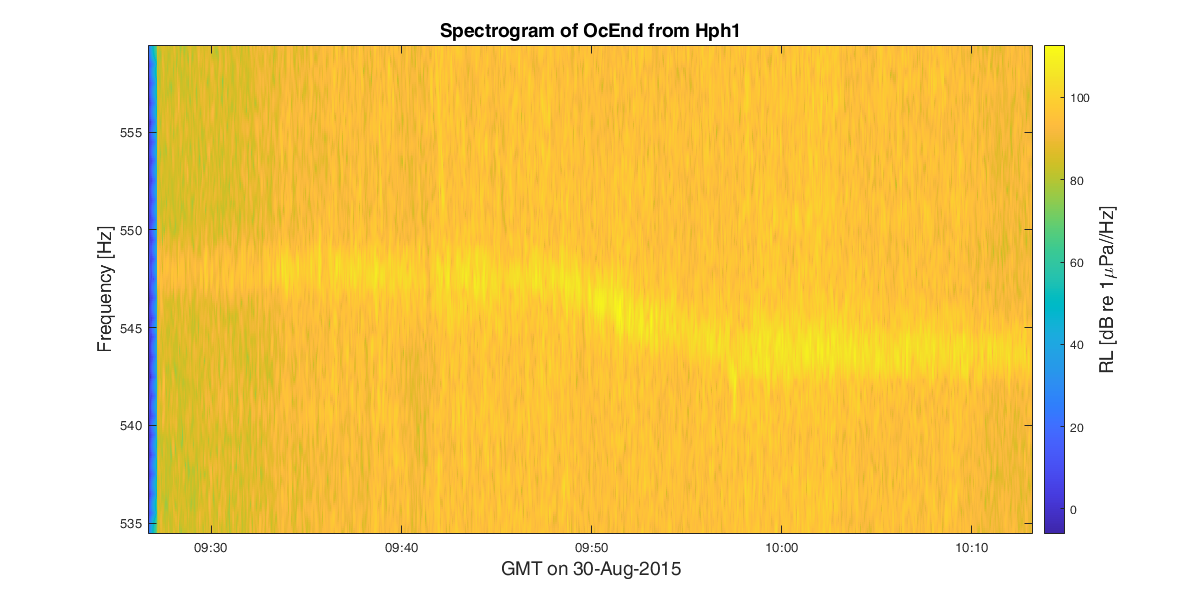

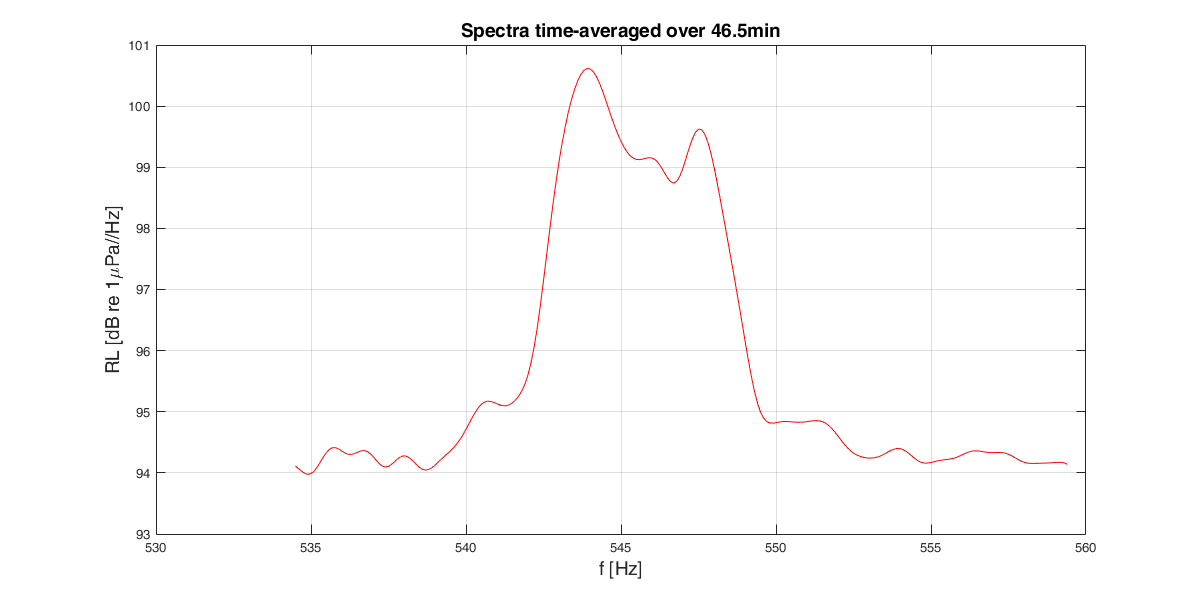

plotSpec(par, tog, TimeVector, Sz, proc, F);

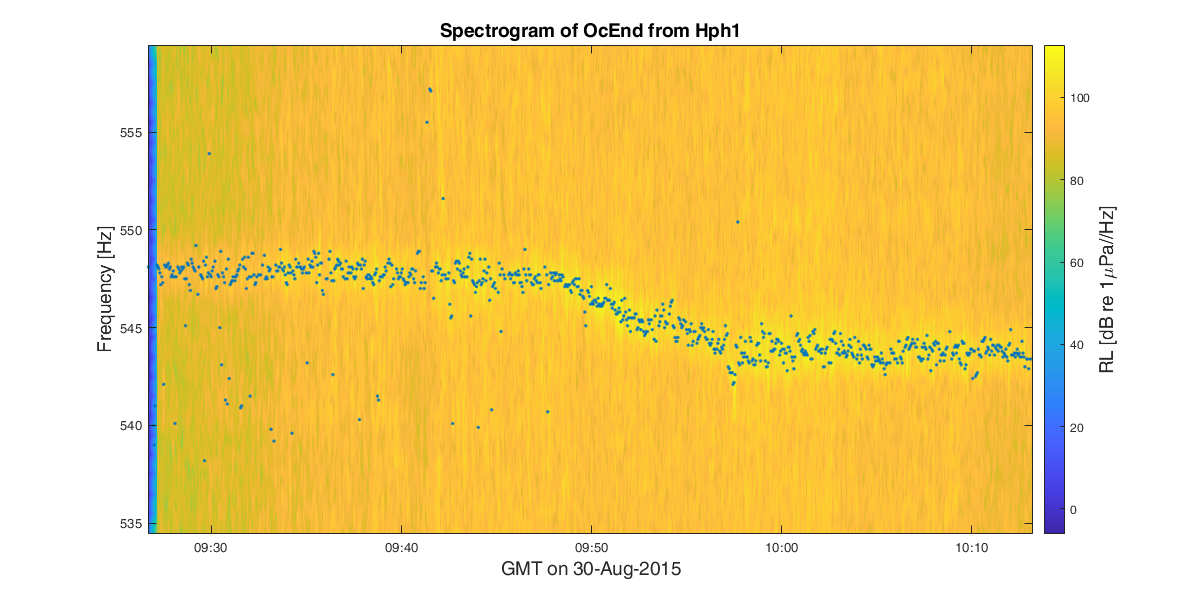

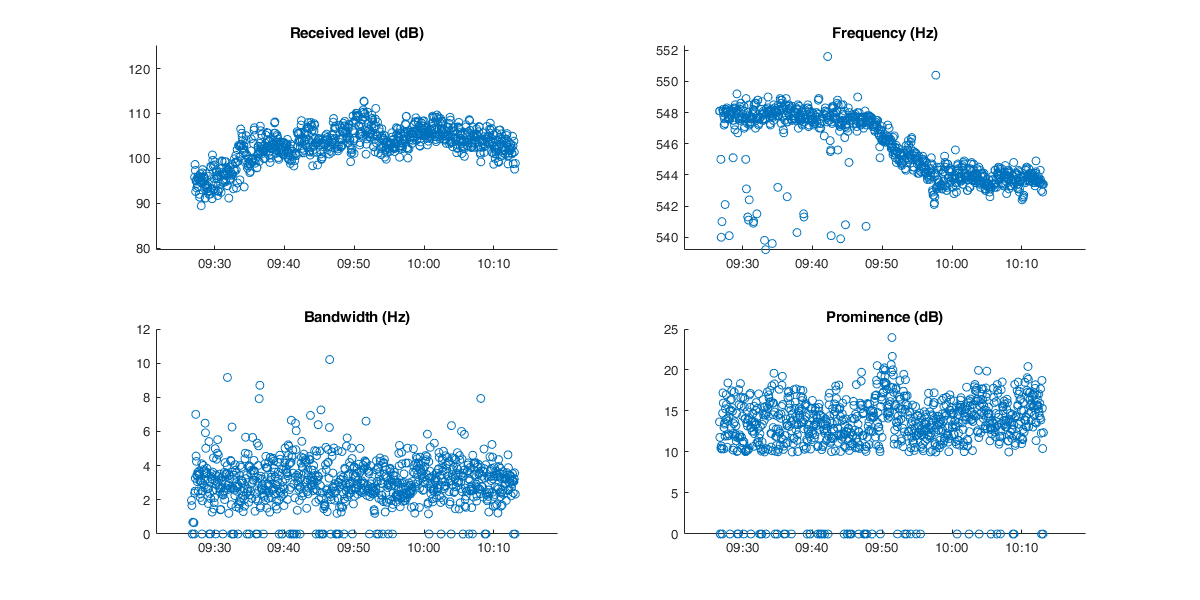

ans = 1

plotSpecWScatter(par, tog, TimeVector, Sz, proc, F, Tonal)